# SPECIES ACCUMULATION

## UPSTREAM

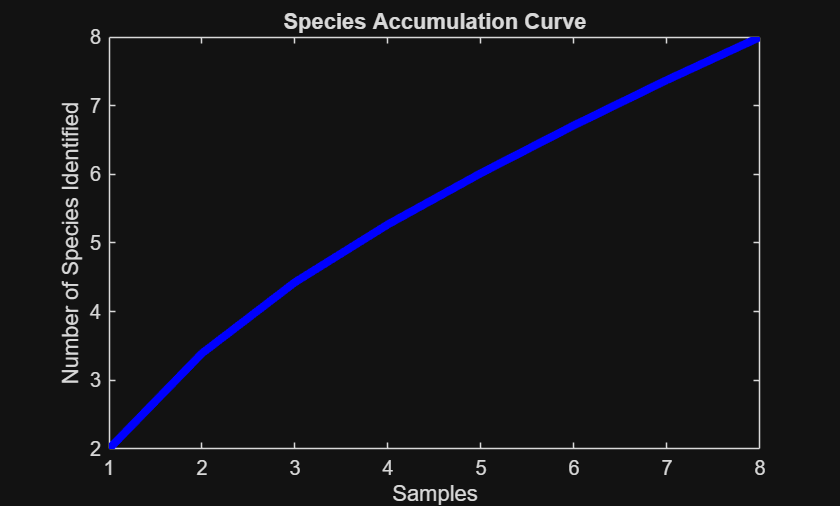


upstream_abundance_data = [7 2 0 0 1 6 0 0;
    0 0 0 0 0 0 0 0;
    0 0 0 0 2 0 0 0;
    0 1 0 0 0 0 0 0;
    7 1 1 1 0 0 0 1;
    0 0 0 0 1 0 0 0;
    1 0 0 0 3 0 0 0;
    0 0 0 0 4 0 0 0;
    0 0 0 0 1 0 0 0];

upstream_spec_data = upstream_abundance_data();
upstream_spec_data(upstream_spec_data > 0) = 1;

num_new_spec_upstream = num_new_spec(upstream_spec_data);

permutation_options = perms([1 2 3 4 5 6 7 8]);
upstream_num_new_spec_perms = num_new_spec_perms(upstream_spec_data, permutation_options);

fig1 = plot(1:8, mean(upstream_num_new_spec_perms), 'b', 'LineWidth', 4);
title("Species Accumulation Curve");
ylabel("Number of Species Identified");
xlabel("Samples");
saveas(fig1, "upstream_spec_acc.png");

## DOWNSTREAM

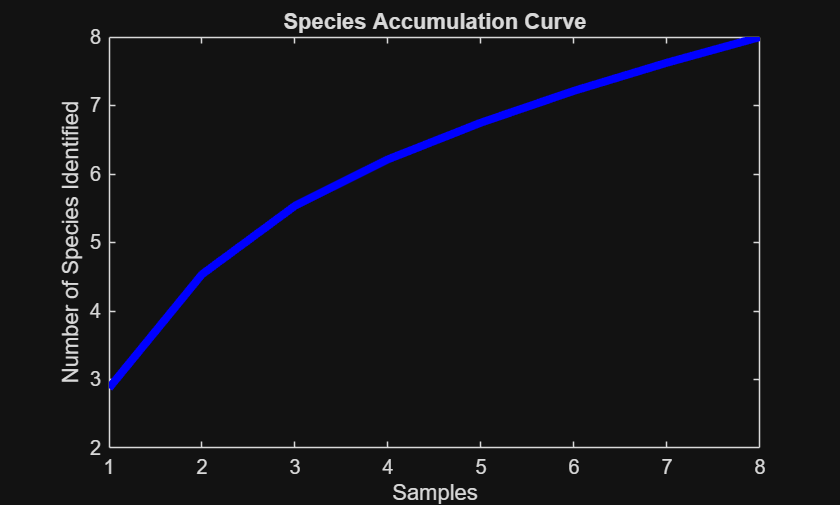


downstream_abundance_data = [5 3 0 1 9 0 4 0;
    0 0 0 0 1 0 0 0;
    0 0 0 0 1 0 0 0;
    2 0 1 0 1 0 1 1;
    5 0 2 0 0 6 1 1;
    0 0 0 0 0 0 0 0;
    1 1 0 0 0 0 1 0;
    0 0 0 0 0 0 29 1;
    0 0 0 0 0 0 5 0];

downstream_spec_data = downstream_abundance_data();
downstream_spec_data(downstream_spec_data > 0) = 1;

num_new_spec_downstream = num_new_spec(downstream_spec_data);

downstream_num_new_spec_perms = num_new_spec_perms(downstream_spec_data, permutation_options);

fig2 = plot(1:8, mean(downstream_num_new_spec_perms), 'b', 'LineWidth', 4);
title("Species Accumulation Curve");
ylabel("Number of Species Identified");
xlabel("Samples");
saveas(fig2, "downstream_spec_acc.png");

## PLOT BOTH

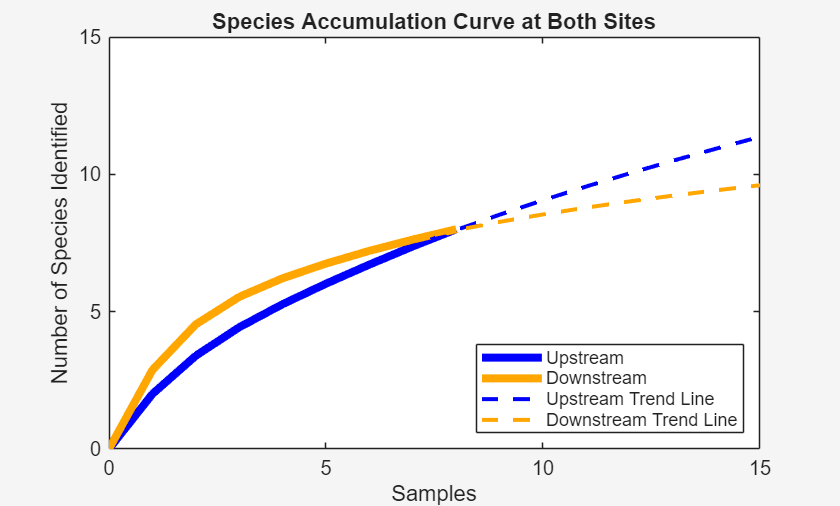

domain = 0:8;
domain_extended = 1:15;
mean_upstream_num_new_spec_perms = [0 mean(upstream_num_new_spec_perms)];
mean_downstream_num_new_spec_perms = [0 mean(downstream_num_new_spec_perms)];

%find fits
upstream_fit = fit((1:8)', mean(upstream_num_new_spec_perms)', 'power2');
upstream_fit_a = 3.276;
upstream_fit_b = 0.4982;
upstream_fit_c = -1.259;
upstream_trend = upstream_fit_a .* domain_extended .^ (upstream_fit_b) + upstream_fit_c;
downstream_fit = fit((1:8)', mean(downstream_num_new_spec_perms)', 'power2');
downstream_fit_a = 49.97;
downstream_fit_b = 0.04661;
downstream_fit_c = -47.09;
downstream_trend = downstream_fit_a .* domain_extended .^ (downstream_fit_b) + downstream_fit_c;

fig3 = plot(domain, mean_upstream_num_new_spec_perms, 'b', 'LineWidth', 4);
hold on;
plot(domain, mean_downstream_num_new_spec_perms, 'Color', [1, 0.65, 0], 'LineWidth', 4);
plot(domain_extended, upstream_trend, 'b', 'LineStyle', '--', 'LineWidth', 2);
plot(domain_extended, downstream_trend, 'Color', [1, 0.65, 0], 'LineStyle', '--', 'LineWidth', 2);
title("Species Accumulation Curve at Both Sites");
legend('Upstream', 'Downstream', 'Upstream Trend Line', 'Downstream Trend Line', 'Location', 'southeast');
ylabel("Number of Species Identified");
xlabel("Samples");
ylim([0 15]);
theme("light");
saveas(fig3, "spec_acc_linear.png");